
%% provo a far funzionare la simulazione
addpath('funzioni')  
addpath('Sottoclassi_di_Distributions') 

% Matrice di adiacenza (3 nodi)
% Nodo 1 → Nodo 2 (con probabilità 1)
% Nodo 2 → Nodo 3 (con probabilità 1)
% Nodo 3 → Sink (rimane lì: loop su se stesso)

matr_adiac = {
    0, 0.4, 0.6, 0, 0, 0;
    0, 0, 0, @(x) x.peso == 1, @(x) x.peso == 0, 0;
    0, 0, 0, 0, 0, 1;
    0.2, 0, 0, 0, 0, 0.8;
    0, 0, 0, 0, 0, 1;
    0, 0, 0, 0, 0, 1;
   }

matr_adiac = 6×6 cell array
    {[     0]}    {[0.4000]}    {[0.6000]}    {[          0]}    {[          0]}    {[     0]}
    {[     0]}    {[     0]}    {[     0]}    {@(x)x.peso==1}    {@(x)x.peso==0}    {[     0]}
    {[     0]}    {[     0]}    {[     0]}    {[          0]}    {[          0]}    {[     1]}
    {[0.2000]}    {[     0]}    {[     0]}    {[          0]}    {[          0]}    {[0.8000]}
    {[     0]}    {[     0]}    {[     0]}    {[          0]}    {[          0]}    {[     1]}
    {[     0]}    {[     0]}    {[     0]}    {[          0]}    {[          0]}    {[     1]}


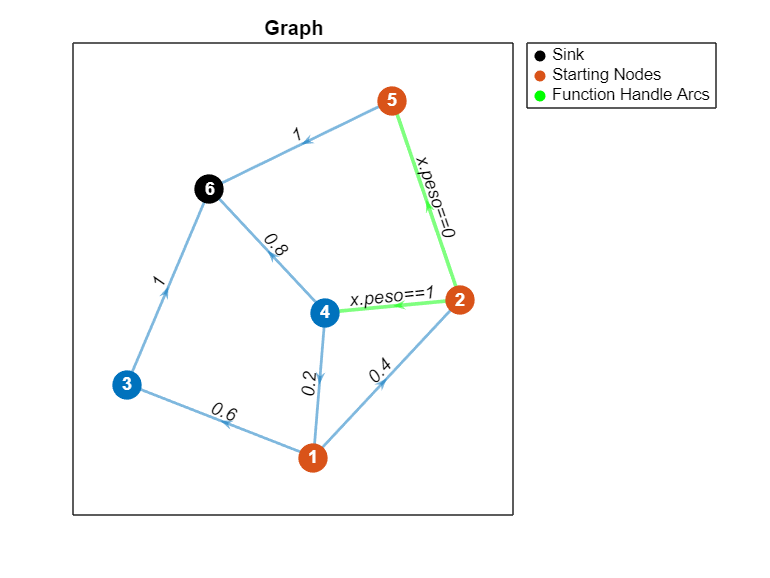


n = size(matr_adiac, 1);


% Una distribuzione per ciascun nodo: solo il primo riceve arrivi esterni
distr_arrivo = cell(n,1);
distr_arrivo{1} = Exponential(20);  
distr_arrivo{2} = Exponential(60);
distr_arrivo{3} = -1;
distr_arrivo{4} = -1;
distr_arrivo{5} = Uniform(20,20,true);  
distr_arrivo{6} = -1;  

% Una matrice per ciascun nodo con distribuzioni di servizio per ciascun nodo (1 server per nodo)
distr_servizio = cell(n,1);
distr_servizio{1} = Exponential(30);  
distr_servizio{2} = Exponential(2);
distr_servizio{3} = Exponential(18);
distr_servizio{4} = Exponential(1);
distr_servizio{5} = Uniform(5,20,false);
distr_servizio{6} = Uniform(inf, inf, false);

% Una matrice per ciascun nodo con policy per cosa
policy = cell(n,1);
policy{1} = 'FIFO';
policy{2} = 'FIFO';
policy{3} = 'LIFO';
policy{4} = 'FIFO';
policy{5} = 'FIFO';
policy{6} = 'FIFO';

% Costruzione dell'oggetto Network
net = Network(matr_adiac, distr_arrivo, distr_servizio, policy);
stampa_grafo(net)

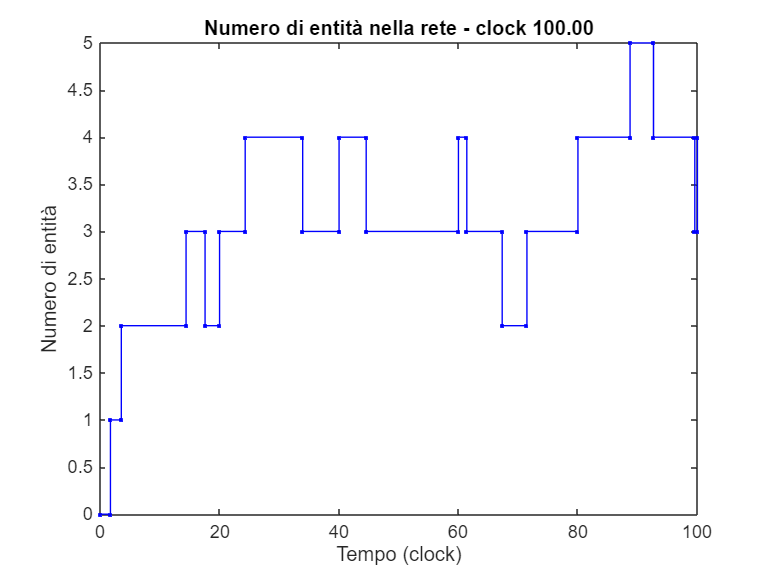


 ********************************* 
 INIZIO SIMULAZIONE ...  
 CLOCK = 1.73
 L'entità 1 è stata generata al nodo 2. 
 L'entità 1 ha iniziato il servizio presso il server 1 del nodo 2. 
 
 CLOCK = 2.82
 L'entità 1 ha terminato il servizio al nodo 2 ed è passata al nodo 5. 
 L'entità 1 ha iniziato il servizio presso il server 1 del nodo 5. 
 
 CLOCK = 3.55
 L'entità 2 è stata generata al nodo 1. 
 L'entità 2 ha iniziato il servizio presso il server 1 del nodo 1. 
 
 CLOCK = 14.39
 L'entità 3 è stata generata al nodo 1. 
 
 CLOCK = 17.57
 L'entità 1 ha terminato il servizio al nodo 5 ed è passata al nodo 6. 
 
 CLOCK = 20.00
 L'entità 3 è stata generata al nodo 5. 
 L'entità 3 ha iniziato il servizio presso il server 1 del nodo 5. 
 
 CLOCK = 24.29
 L'entità 4 è stata generata al nodo 2. 
 L'entità 4 ha iniziato il servizio presso il server 1 del nodo 2. 
 
 CLOCK = 27.58
 L'entità 4 ha terminato il servizio al nodo 2 ed è passata al nodo 5. 
 
 CLOCK = 33.07
 L'entità 2 ha terminato il 

% Inizializzo una simulazione
attributi_entita = [];
attributi_entita.peso =  {0, 1};
sim = Simulation(net, attributi_entita);
figure;
le = sim.run(100,true);